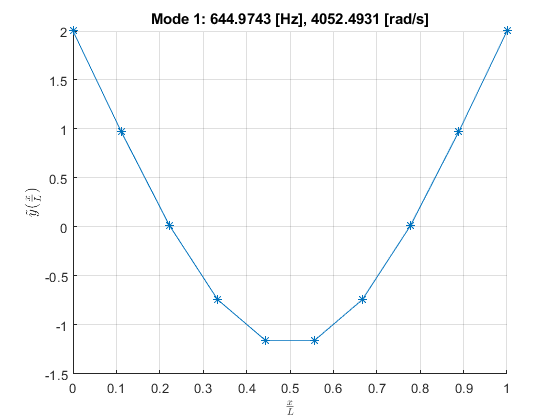

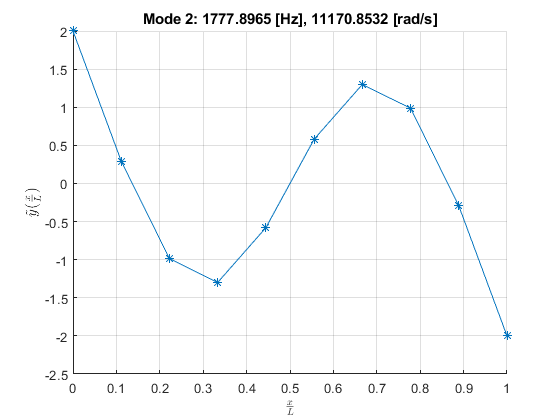

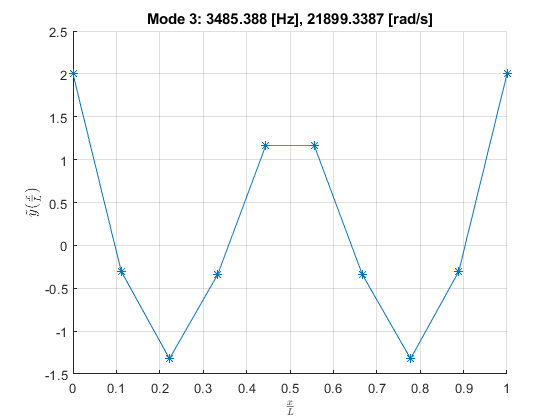

beam.E      = 2e9;                  % (Pa)      modulus of elasticity
beam.rho    = 1270;                 % (kg/m^3)  density
% beam.L      = 10e-2;                % (m)       beam length
% beam.w      = 2e-2;                 % (m)       beam width
% beam.t      = 5e-3;                 % (m)       beam thickness
beam.L = 10e-2;
beam.w = 2e-2;
beam.t = 5e-3;
beam.I      = (beam.w*beam.t^3)/12; % (m^4)     area moment of inertia
beam.A      = beam.w * beam.t;      % (m^2)     beam area
beam.m      = beam.rho * beam.A;    % (kg/)     mass per unit length
% beam.n      = 10;                  % (null)    nodes
beam.n = 10;
cond = "Free-Free";
modes = [1:3];

beam = beamModes(beam,modes,cond);
beamModesPlot(beam)